clc
clear

Esercizio 1.

Chiedo un numero in input e verifico che sia intero, pari e compreso tra 20 e 30:

.

%Se è divisibile per 2 con resto 0 è anche divisibile per 1, quindi intero
n = -1;
while(mod(n, 2) ~= 0 || n < 20 || n > 30)
    n = input("Inserisci un numero intero tra 20 e 30: ");
end

Ora devo costruire una matrice nxn:

C = ones(n);
for k = n - 1 : -1 : 1
    for i = 1 : 1 : k
        for j = 1 : 1 : k
            C(i, j) = C(i, j) + 1;
        end
    end
end
C
[V, D] = eigs(C);
spectrum = diag(D);
rho = max(abs(spectrum));

disp("Lo spettro di C è: ");
disp(spectrum);
disp("Mentre il raggio spettrale è: ");
disp(rho);

clc
clear

Esercizio 2.

Creo 10 matrici (una alla volta) con dimensione da 100 a 1000 con numeri compresi tra 10 e 30:

errore = zeros(10, 1);
k = 1;
for i = 100 : 100 : 1000

    A = 10 + 20 * rand(i);
    
    [P, L, U] = gauss_palu(A);

    x = ones(i, 1);
    b = A * x;

    y = L\(P*b);
    x1 = U\y;

    errore(k) = norm(x1 - x) / norm(x);
    k = k + 1;
end
vec = 100 : 100 : 1000;
vec = vec';
t = table(vec, errore, 'VariableNames', {'Dimensione matrice', 'errore relativo'});
disp(t);

    Dimensione matrice    errore relativo
    __________________    _______________

            100             1.6371e-13   
            200             6.2334e-13   
            300             9.7054e-11   
            400             3.0134e-11   
            500             4.8806e-12   
            600             3.1066e-12   
            700             1.0589e-12   
            800             1.2219e-12   
            900             1.3614e-12   
           1000             1.1971e-11   



clc
clear

Esericizio 3.

Funzione:

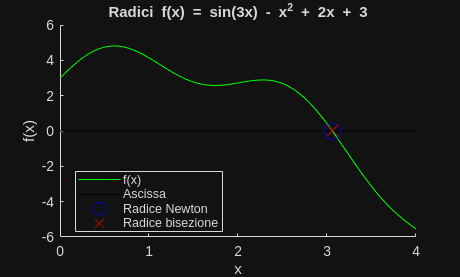

f = @(x) sin(3 .* x) - x .* x + 2 .* x + 3;
fder = @(x) 3 .* cos(3 .* x) - 2 .* x + 2;
[xn, kn] = newton(f, fder, 1, 10e-5, 100);
[xb, kb] = bisezione(f, 0, 4, 10e-5, 100);

x = linspace(0, 4, 200);
figure;
hold on;

xlabel("x");
ylabel("f(x)");
title("Radici f(x) = sin(3x) - x^2 + 2x + 3");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(xn, f(xn), "Ob", "DisplayName", "Radice Newton", "MarkerSize", 12);
plot(xb, f(xb), "Xr", "DisplayName", "Radice bisezione", "MarkerSize", 12);

legend("Location", "best");

hold off;

function [P, L, U] = gauss_palu(A)

    [m, n] = size(A);
    if m ~= n
        error("La matrice deve essere quadrata");
    end

    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end

    L = zeros(n);
    P = eye(n);

    for k = 1 : n-1

        [~, index] = max(abs(A(k:n, k)));
        l = index + k - 1;

        A([k l], :) = A([l k], :);
        L([k l], :) = L([l k], :);
        P([k l], :) = P([l k], :);
        
        for i = k+1 : n
            m = A(i, k) / A(k, k);

            A(i, :) = A(i, :) - m * A(k, :);

            L(i, k) = m;
        end
    end
    U = A;
    L = L + eye(n);
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)
    kn = 1;
    xn = -1;
    f1 = fder(x0);

    if(abs(f(x0)) < tau)
        xn = x0;
        return;
    end

    while(kn < kmax && abs(f(xn)) >= tau)
        
        if(abs(f1) < tau)
            error("Cambia x0");
        end

        xn = x0 - f(x0) / f1;
        
        x0 = xn;
        f1 = fder(x0);

        kn = kn + 1;
    end
end

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    kb = 1;
    xb = -1;
    fxb = -1;

    fa = f(a);
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [" + a, + ", " + b + "]");
    end

    while(kb < kmax && abs(fxb) >= tau)
       
        xb = (a + b) / 2;
        
        fxb = f(xb);
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end


        kb = kb + 1;
    end
    
end